# 二、测试模型

### 2.1 加载Yolov2模型

clear;clc;
load Yolo2Model.mat

### 2.2 读取图像

[file,path] = uigetfile("测试集\");
filepath = fullfile(path,file);

### 2.3 目标检测

if file ~= 0
    img = imread(filepath);
    [bboxes,scores] = detect(detector,img); %利用训练好Yolov2模型进行检查
end
scores = strcat(string(round(scores,2)*100),"%");
number = string(numel(scores));

### 2.4 输出识别结果

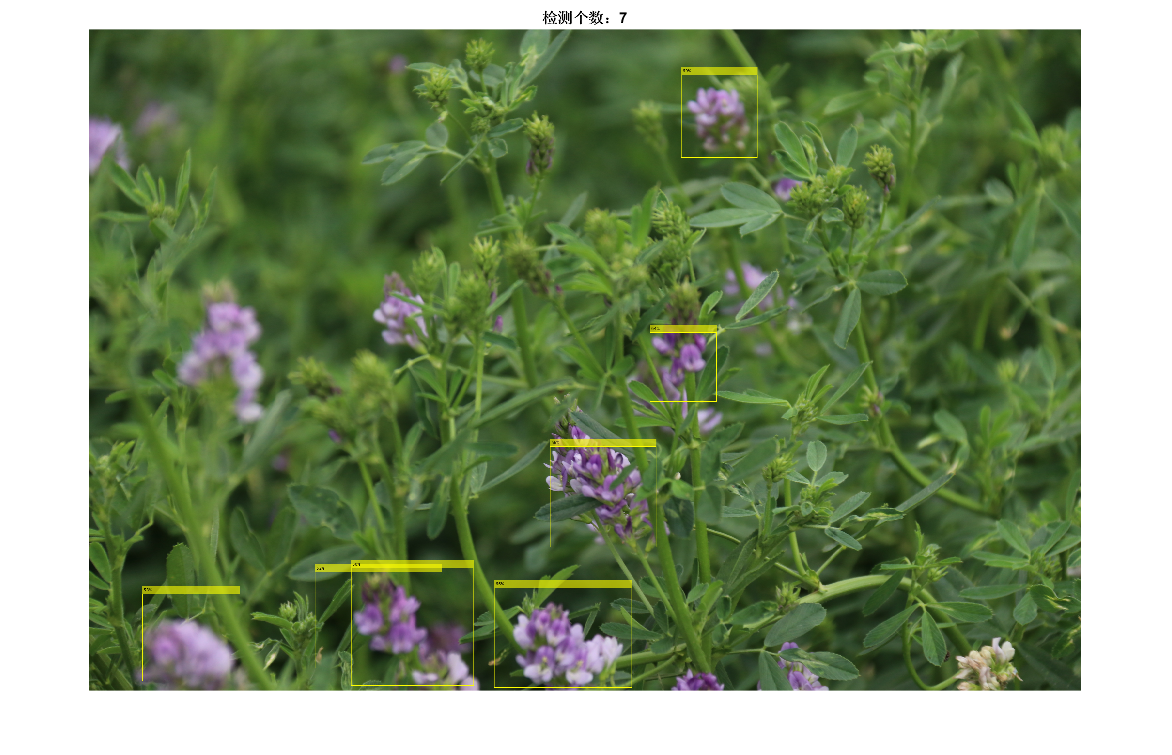

if(~isempty(bboxes))
    img = insertObjectAnnotation(img,'rectangle',bboxes,scores);
end
imshow(img),title(strcat("检测个数：",number));